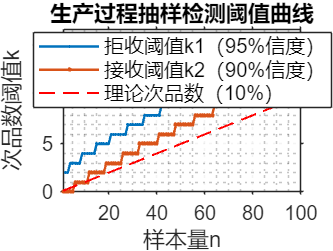

%% 生产过程抽样检测模型：双情形独立求解与可视化
% 假设：检查正确率100%，零件次品率服从二项分布B(n,p0)，p0=10%（标称值）
% 情形1：95%信度认定p>10% → 拒收（概率约束：P(k≥k1|n,p0) ≤ 0.05）
% 情形2：90%信度认定p≤10% → 接收（概率约束：P(k≤k2|n,p0) ≥ 0.9）

clear; clc; close all;

%% 1. 核心参数设置
p0 = 0.1;                  % 标称次品率（10%）
conf_reject = 0.05;        % 情形1：拒收信度（≤5%）
conf_accept = 0.9;         % 情形2：接收信度（≥90%）
n_range = 1:100;          % 样本量n的搜索范围
k1 = zeros(1, length(n_range));  % 情形1：各n对应的拒收阈值k1
k2 = zeros(1, length(n_range));  % 情形2：各n对应的接收阈值k2
valid_n1 = false(1, length(n_range));  % 情形1：是否存在有效k1
valid_n2 = false(1, length(n_range));  % 情形2：是否存在有效k2


%% 2. 独立求解两种情形的k-n关系（核心计算）
for i = 1:length(n_range)
    n = n_range(i);  % 当前样本量
    
    % -------------------------- 情形1：求解拒收阈值k1 --------------------------
    found_k1 = false;
    for k_candidate = 0:n
        if k_candidate == 0
            prob_cdf = 0;
        else
            prob_cdf = binocdf(k_candidate - 1, n, p0);
        end
        if (1 - prob_cdf) <= conf_reject
            k1(i) = k_candidate;
            valid_n1(i) = true;
            found_k1 = true;
            break;
        end
    end
    if ~found_k1
        k1(i) = NaN;
    end
    
    % -------------------------- 情形2：求解接收阈值k2 --------------------------
    found_k2 = false;
    for k_candidate = n:-1:0
        prob_cdf = binocdf(k_candidate, n, p0);
        if prob_cdf <= conf_accept
            k2(i) = k_candidate;
            valid_n2(i) = true;
            found_k2 = true;
            break;
        end
    end
    if ~found_k2
        k2(i) = NaN;
    end
end


%% 3. 提取有效数据
n1_valid = n_range(valid_n1);
k1_valid = k1(valid_n1);
n2_valid = n_range(valid_n2);
k2_valid = k2(valid_n2);


%% 4. 绘图与美化
figure('Position', [100 100 800 600]);  % 设置画布大小

% 绘制主曲线
plot(n1_valid, k1_valid, '-*', 'MarkerSize', 8, 'LineWidth', 1.2, ...
     'DisplayName', '拒收阈值k1（95%信度）',Markersize=1);
hold on;
plot(n2_valid, k2_valid, '-o', 'MarkerSize', 8, 'LineWidth', 1.2, ...
     'DisplayName', '接收阈值k2（90%信度）',Markersize=1);

% 添加理论次品率参考线（p0=10%）
plot(n_range, p0*n_range, '--r', 'LineWidth', 1, ...
     'DisplayName', '理论次品数（10%）');

% 添加网格线
grid on;
grid minor;  % 显示次要网格线
set(gca, 'GridLineStyle', ':', 'GridColor', [0.7 0.7 0.7]);

% 添加坐标轴标签和标题
xlabel('样本量n', 'FontSize', 12);
ylabel('次品数阈值k', 'FontSize', 12);
title('生产过程抽样检测阈值曲线', 'FontSize', 14, 'FontWeight', 'bold');

% 设置坐标轴范围
xlim([min(n_range) max(n_range)]);
ylim([0 max([k1_valid k2_valid])+1]);

% 添加图例
legend('Location', 'best', 'FontSize', 10);

% 美化坐标轴刻度
set(gca, 'FontSize', 10, 'TickDir', 'out');

hold off;

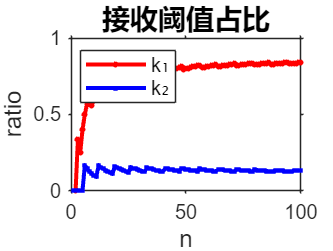

ratio1 = 1-k1_valid ./ n1_valid;  % 情形1：k1/n（拒收阈值占比）
ratio2 = k2_valid ./ n2_valid;  % 情形2：k2/n（接收阈值占比）

% 绘制比值曲线
plot(n1_valid, ratio1, 'r-o', ...
     'LineWidth', 2, 'MarkerSize', 1, 'MarkerFaceColor', 'r', ...
     'DisplayName', 'k₁');
hold on;
plot(n2_valid, ratio2, 'b-s', ...
     'LineWidth', 2, 'MarkerSize', 1, 'MarkerFaceColor', 'b', ...
     'DisplayName', 'k₂');
set(gca, 'FontSize', 10, 'TickDir', 'out');
xlabel('n', 'FontSize', 12);
ylabel('ratio', 'FontSize', 12);
title('接收阈值占比', 'FontSize', 14, 'FontWeight', 'bold');
legend('Location', 'best', 'FontSize', 10);